# OGLO notebook 4d

hnxj@github

### MT

xG = z{7};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_mt = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_mt(ik, :, :) = squeeze(pgx_mt(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
cond : 4
cond : 7
cond : 3
cond : 2
cond : 6
cond : 8
cond : 10
cond : 12
cond : 11
cond : 9
cond : 5
cond : 1


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs07_OGLO_MT", "pgx_mt", "-v7.3");

load("lfpData\TFRs07_OGLO_MT.mat", "pgx_mt");

pgx = zeros(size(pgx_mt));

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_mt(ij, ik, :))/mean(pgx_mt(ij, ik, 1:15));

    end

end

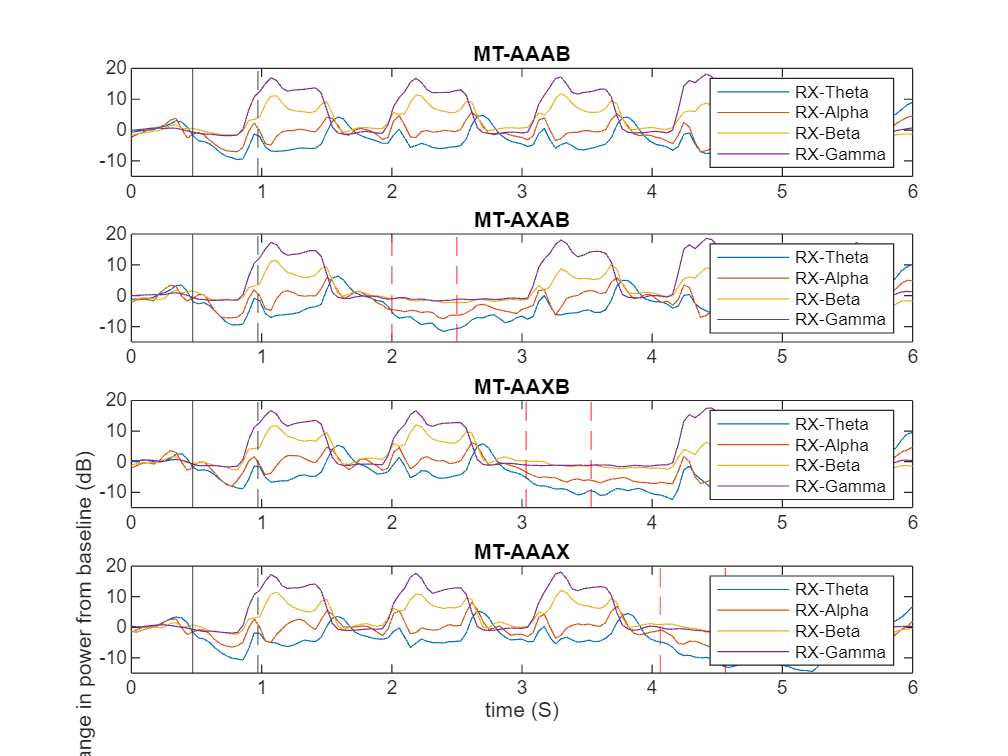

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT-AAAB");
ylim([-15 20]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-AXAB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-AAXB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MT-AAAX");ylim([-15 20]);
% xlim([0.4 6.0]);

fname = "MT_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

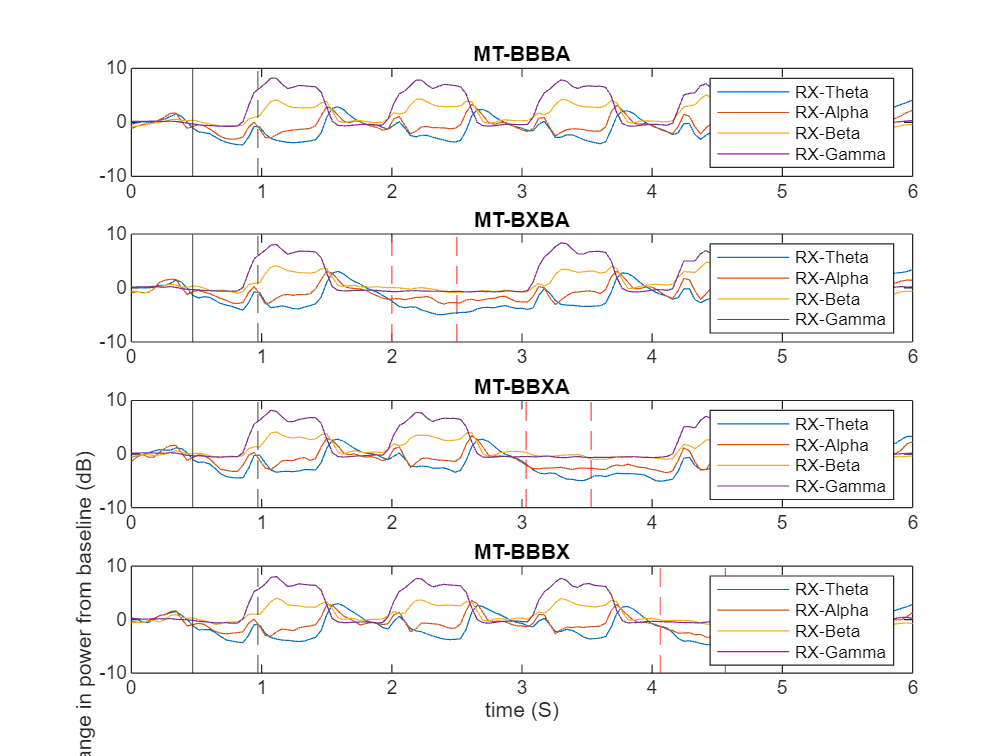

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT-BBBA");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-BXBA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-BBXA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MT-BBBX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "MT_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

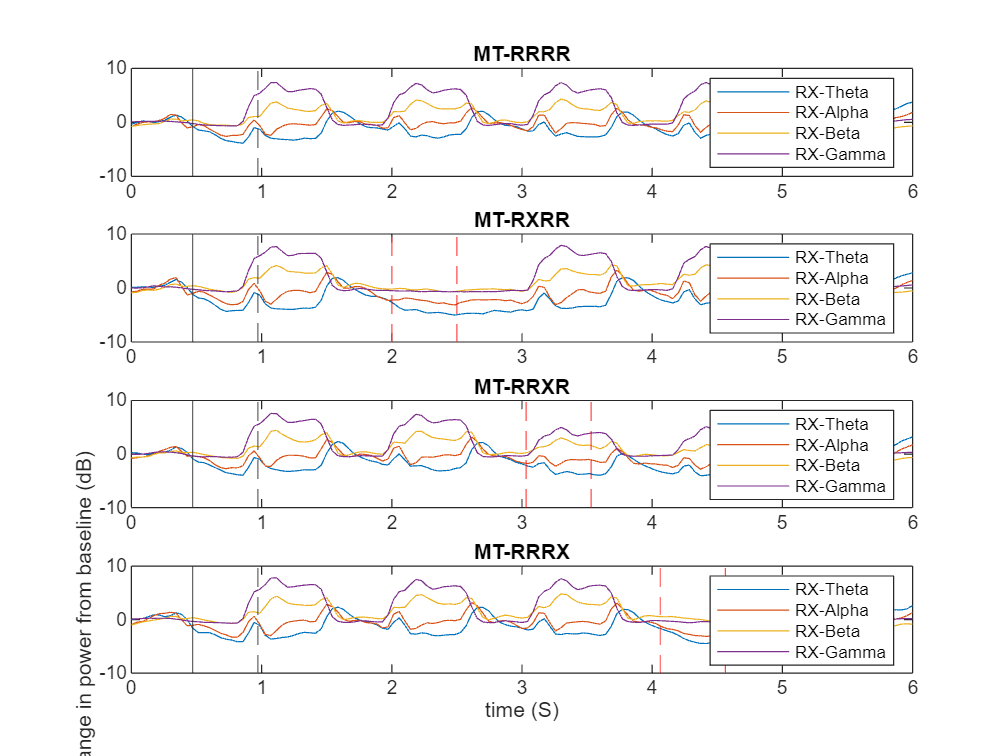

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT-RRRR");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-RXRR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MT-RRXR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MT-RRRX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "MT_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");

### MST

xG = z{8};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_mst = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_mst(ik, :, :) = squeeze(pgx_mst(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 4
cond : 7
cond : 3
cond : 2
cond : 6
cond : 10
cond : 11
cond : 12
cond : 8
cond : 9
cond : 5
cond : 1


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs08_OGLO_mst", "pgx_mst", "-v7.3");

load("lfpData\TFRs08_OGLO_mst.mat", "pgx_mst");

pgx = zeros(size(pgx_mst));

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_mst(ij, ik, :))/mean(pgx_mst(ij, ik, 1:15));

    end

end

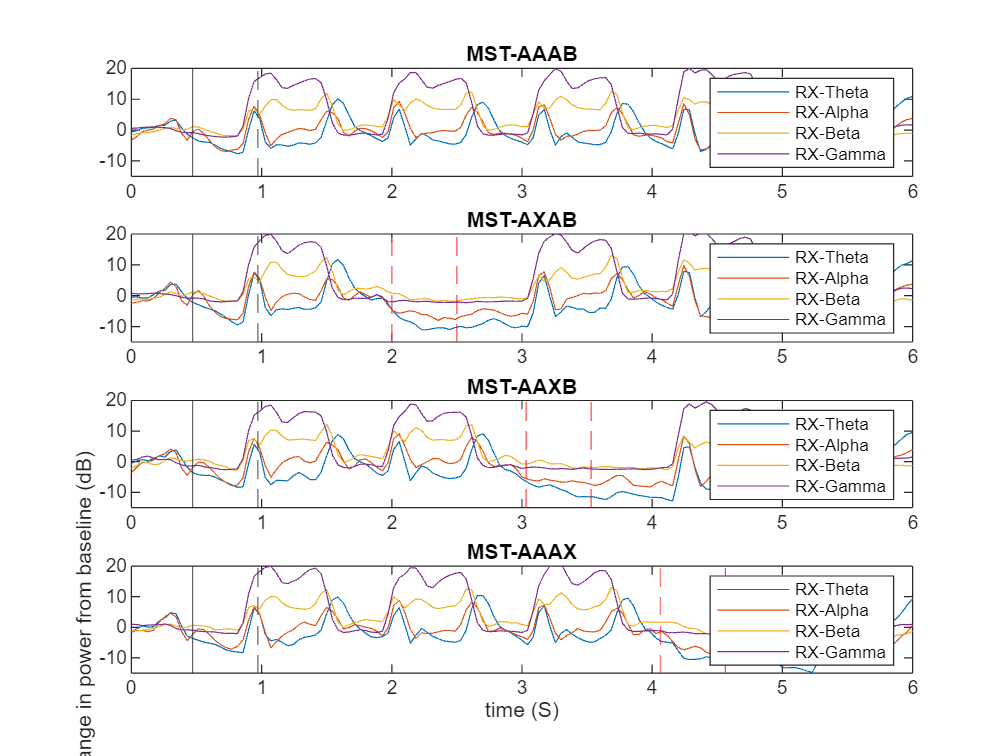

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MST-AAAB");
ylim([-15 20]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-AXAB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-AAXB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MST-AAAX");ylim([-15 20]);
% xlim([0.4 6.0]);

fname = "MST_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

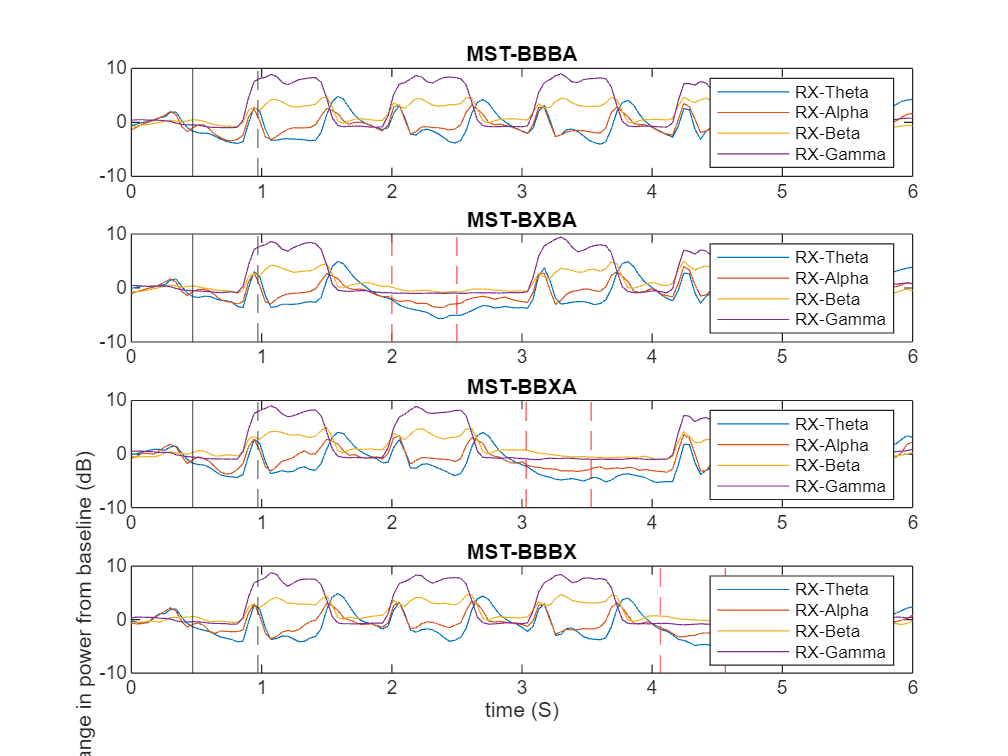

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MST-BBBA");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-BXBA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-BBXA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MST-BBBX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "MST_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

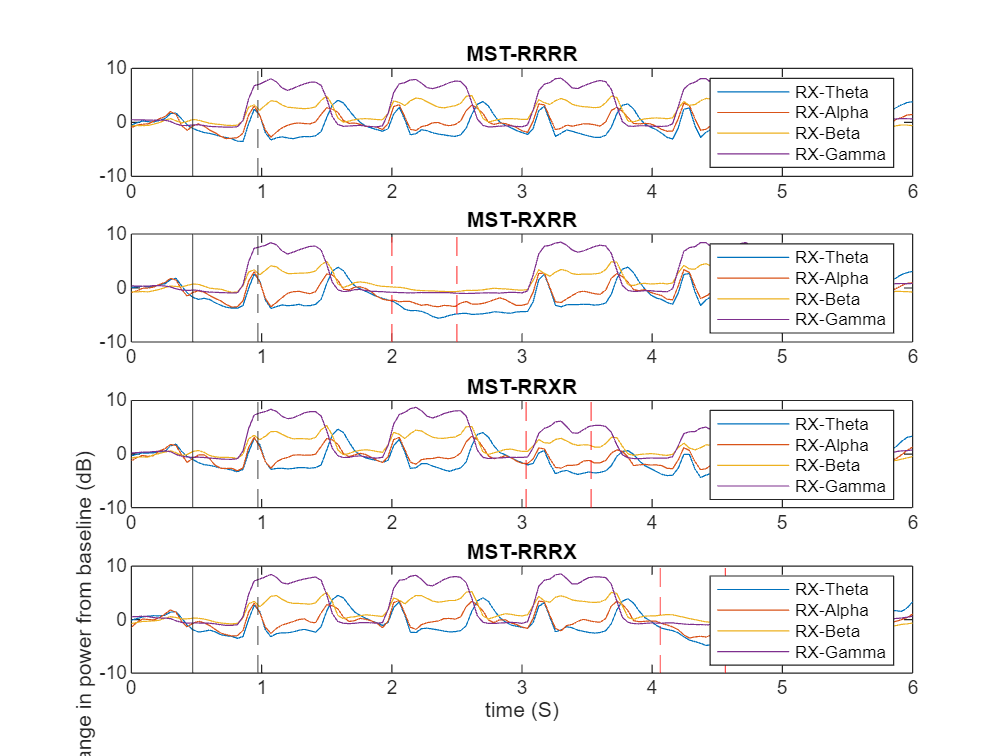

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MST-RRRR");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-RXRR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("MST-RRXR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("MST-RRRX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "MST_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");